Sistemas Nebulosos - UFMG 2021 - Luiz Gabriel Aragão 2014806480

Exercícios computacionais - Parte 1

close all
clc

%espaço amostral
t = (0:0.0001:8)'; 

%% Operador Complemento de Zadeh 
conjNeb = trimf(t,[1,4,7]);
compZadeh = 1 - conjNeb;

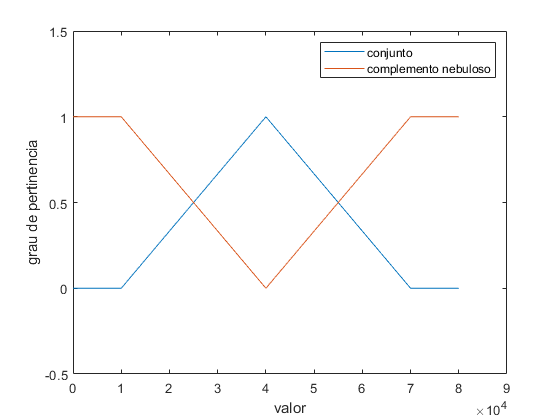

%% Plot Complemento de Zadeh 
plot(conjNeb) 
ylim([-.5 1.5]);
hold on
plot(compZadeh)
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend('conjunto','complemento nebuloso');

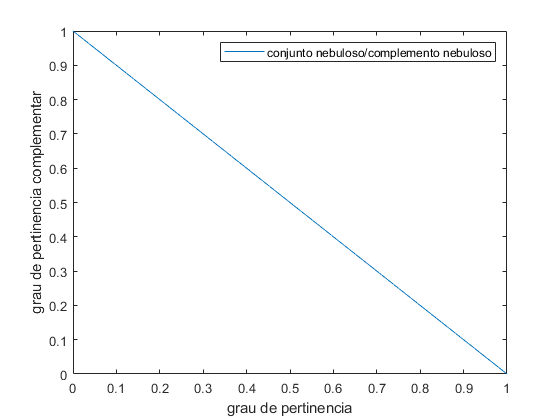

figure
plot(conjNeb,compZadeh)
hXLabel = xlabel('grau de pertinencia');
hYLabel = ylabel('grau de pertinencia complementar');
hLegend = legend('conjunto nebuloso/complemento nebuloso');

%% Operador Complemento de Sugeno
% parametros sugeno
su = 30;
su1 = -0.70;
su2 = 0.70;

% operador
compSugeno2=(1-conjNeb)./(1+su*conjNeb);
compSugeno3=(1-conjNeb)./(1+su1*conjNeb);
compSugeno4=(1-conjNeb)./(1+su2*conjNeb);


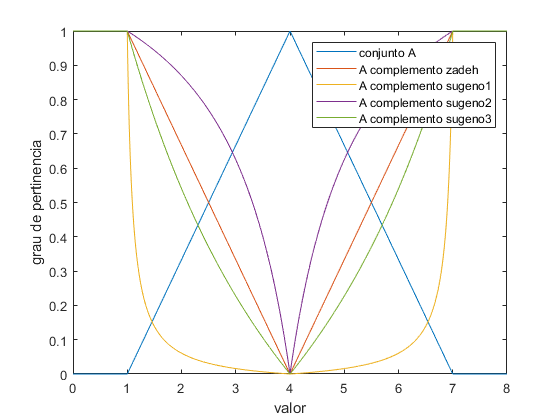

% Plot complemento sugeno
plot( ...
    t,conjNeb, ...
    t,compZadeh, ...
    t,compSugeno2, ...
    t,compSugeno3, ...
    t,compSugeno4)
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'conjunto A', ...
    'A complemento zadeh', ...
    'A complemento sugeno1', ...
    'A complemento sugeno2', ...
    'A complemento sugeno3');

figure

%% Operador Complemento de Yader
% parametros de yader
y1 = 3;
y2 = 9;
compYader = (1-conjNeb.^y1).^(1/y1);
compYader2= (1-conjNeb.^y2).^(1/y2);

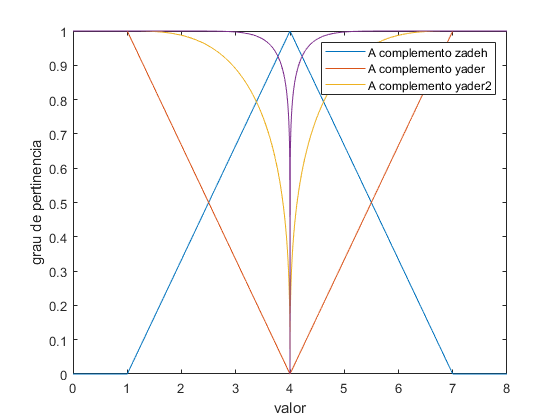

% Plot Complemento Yader
% Plot complemento sugeno
plot( ...
    t,conjNeb, ...
    t,compZadeh, ...
    t,compYader, ...
    t,compYader2)
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'A complemento zadeh', ...
    'A complemento yader', ...
    'A complemento yader2');

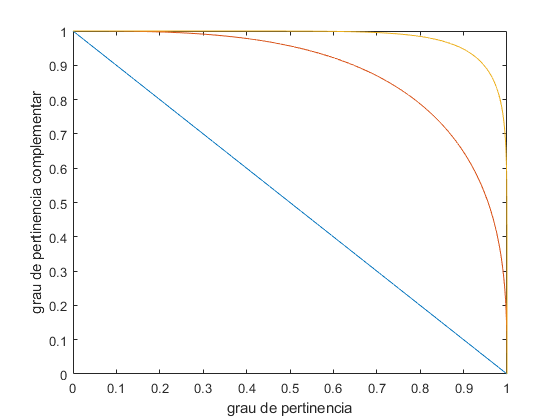

figure
plot(...
    conjNeb,compZadeh, ...
    conjNeb,compYader, ...
    conjNeb,compYader2)
hXLabel = xlabel('grau de pertinencia');
hYLabel = ylabel('grau de pertinencia complementar');

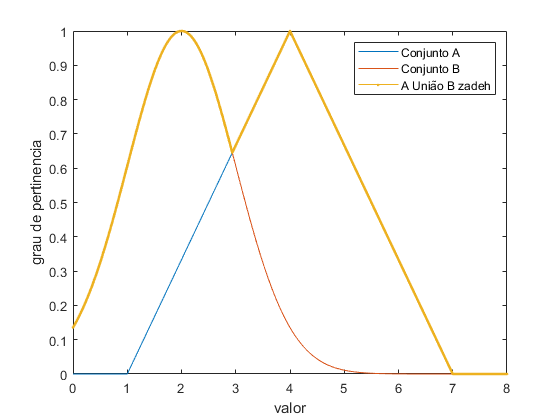

% Operador União de Zadeh
conjNeb2 = gaussmf(t,[1,2]);
uZadeh = max(conjNeb,conjNeb2);
plot(t,conjNeb, ...
    t,conjNeb2, ...
    t,uZadeh,'.-');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A', ...
    'Conjunto B', ...
    'A União B zadeh');

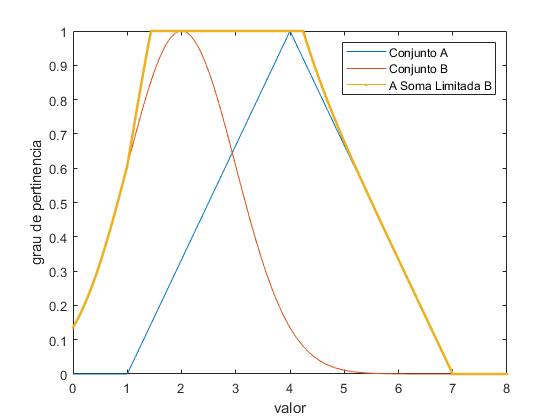

% Operador Soma Limitada
somaLimitada = min(1,conjNeb+conjNeb2);
plot(t,conjNeb, ...
    t,conjNeb2, ...
    t,somaLimitada,'.-');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A', ...
    'Conjunto B', ...
    'A Soma Limitada B');

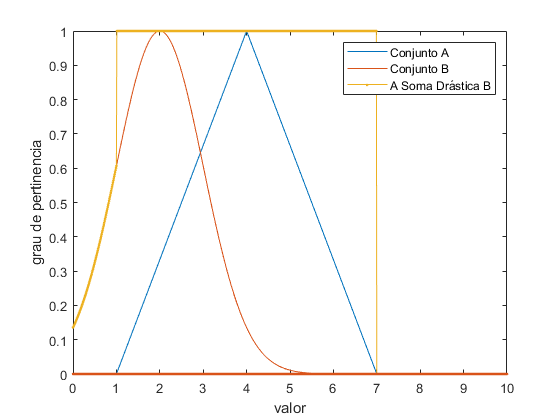

% Operador Soma Drástica
sDrastica = zeros(1001)';
x=(0:0.01:10)';
a= trimf(x,[1,4,7]);
b=gaussmf(x,[1,2]);

for p = 1: length(x)
    if min(a(p),b(p)) == 0
        sDrastica(p) = max(a(p),b(p));
    else
        sDrastica(p) = 1;
    end
end
plot(x,a, ...
    x,b, ...
    x,sDrastica,'.-');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A', ...
    'Conjunto B', ...
    'A Soma Drástica B');

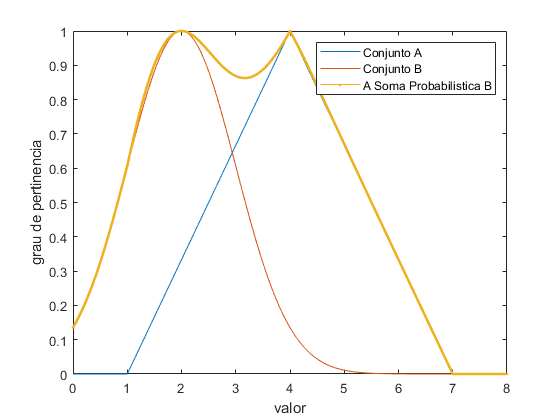

% Operador Soma Limitada
prodDrast = conjNeb + conjNeb2 -(conjNeb.*conjNeb2);
plot(t,conjNeb, ...
    t,conjNeb2, ...
    t,prodDrast,'.-');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A', ...
    'Conjunto B', ...
    'A Soma Probabilistica B');

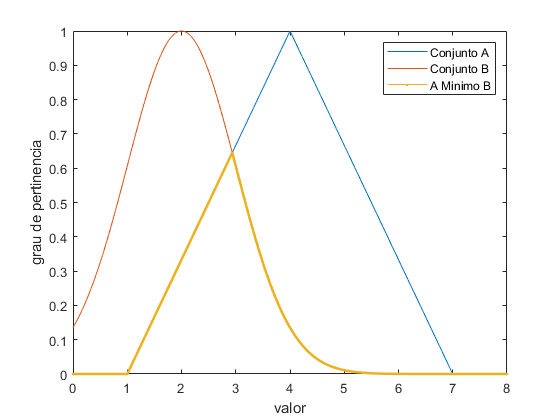

% Operador Minimo
prodDrast = min(conjNeb,conjNeb2);
plot(t,conjNeb, ...
    t,conjNeb2, ...
    t,prodDrast,'.-');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A', ...
    'Conjunto B', ...
    'A Minimo B');

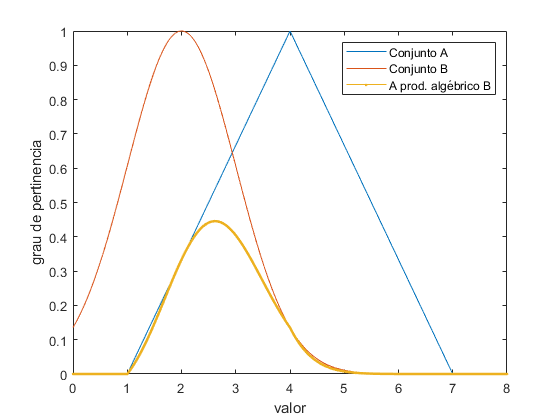

% Operador Produto Algebrico
prodDrast = conjNeb.*conjNeb2;
plot(t,conjNeb, ...
    t,conjNeb2, ...
    t,prodDrast,'.-');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A', ...
    'Conjunto B', ...
    'A prod. algébrico B');

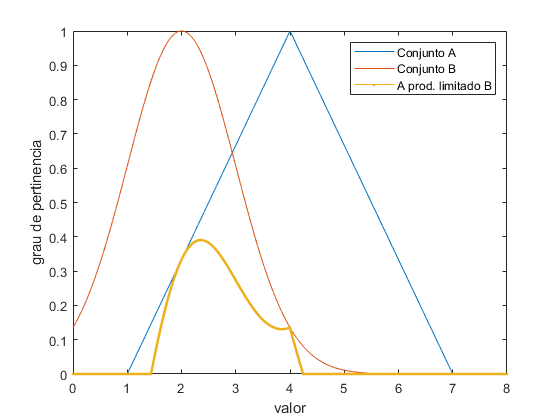

% Operador Produto Limitado
prodDrast = max(0, conjNeb + conjNeb2 - 1);
plot(t,conjNeb, ...
    t,conjNeb2, ...
    t,prodDrast,'.-');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A', ...
    'Conjunto B', ...
    'A prod. limitado B');

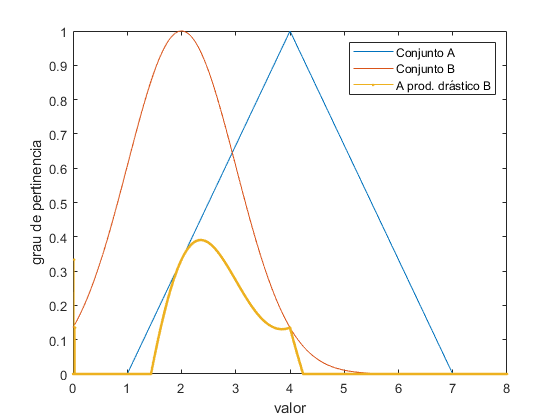

% Operador Produto Drastico
prodDrast = max(0, conjNeb + conjNeb2 - 1);
for p = 1: length(x)
    if b(p) == 1
        prodDrast(p) = a(p);
    elseif a(p) == 1
        prodDrast(p) = b(p);
    else
        prodDrast(p) = 0;
    end
end
plot(t,conjNeb, ...
    t,conjNeb2, ...
    t,prodDrast,'.-');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A', ...
    'Conjunto B', ...
    'A prod. drástico B');

## Erro Quadratico Médio

% dados para simulação
xe = (-2:0.001:2)';
ye = xe.^2;
nPts = length(xe);

sysSugeno = readfis('controle_sugeno.fis');
ySugeno = evalfis(xe,sysSugeno);


sysMamdami = readfis('controle_sugeno.fis');
yMamdami = evalfis(xe,sysMamdami);

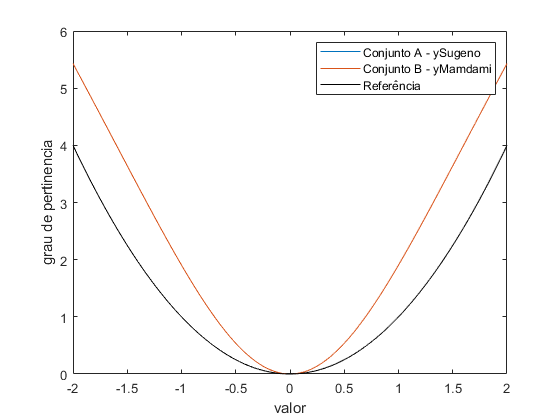


plot(xe,ySugeno, ...
    xe,yMamdami, ...
    xe,ye,'k');
hXLabel = xlabel('valor');
hYLabel = ylabel('grau de pertinencia');
hLegend = legend( ...
    'Conjunto A - ySugeno', ...
    'Conjunto B - yMamdami', ...
    'Referência');

% erro quadratico 
eSugeno = 0;
eMamdami = 0;
for k = 1 :nPts
    eSugeno = eSugeno + (ySugeno(k) - ye(k))^2;
    eMamdami = eMamdami + (yMamdami(k) - ye(k))^2;
end
eSugeno

eSugeno = 3.9227e+03

eMamdami

eMamdami = 3.9227e+03

## Mecanismos de Inferência

Configuração do sistema de inferência nebulosa Mamdami

[System]

Name='controle_mamdami'

Type='mamdani'

Version=2.0

NumInputs=1

NumOutputs=1

NumRules=5

AndMethod='min'

OrMethod='max'

ImpMethod='min'

AggMethod='max'

DefuzzMethod='centroid'

[Input1]

Name='X'

Range=[-2 2]

NumMFs=5

MF1='mf1':'trimf',[-3 -2 -1]

MF2='mf2':'trimf',[-2 -1 0]

MF3='mf3':'trimf',[-1 0 1]

MF4='mf4':'trimf',[0 1 2]

MF5='mf5':'trimf',[1 2 3]

[Output1]

Name='Y'

Range=[0 4]

NumMFs=3

MF1='mf1':'trimf',[0 0 1]

MF2='mf2':'trimf',[0 1 2]

MF3='mf3':'trimf',[2 4 4]

[Rules]

1, 1 (1) : 1

2, 2 (1) : 1

3, 3 (1) : 1

4, 2 (1) : 1

5, 1 (1) : 1

Configuração Sugeno

Configuração do sistema de inferência nebulosa Sugeno

[System]

Name='controle_sugeno'

Type='sugeno'

Version=2.0

NumInputs=1

NumOutputs=1

NumRules=2

AndMethod='prod'

OrMethod='probor'

ImpMethod='prod'

AggMethod='sum'

DefuzzMethod='wtaver'

[Input1]

Name='X'

Range=[-2 2]

NumMFs=2

MF1='mf1':'gaussmf',[2 -3]

MF2='mf2':'gaussmf',[-2 3]

[Output1]

Name='Y'

Range=[0 4]

NumMFs=2

MF1='mf1':'linear',[3 0]

MF2='mf2':'linear',[-3 0]

[Rules]

1, 2 (1) : 1

2, 1 (1) : 1

## Reconhecimento de padrões

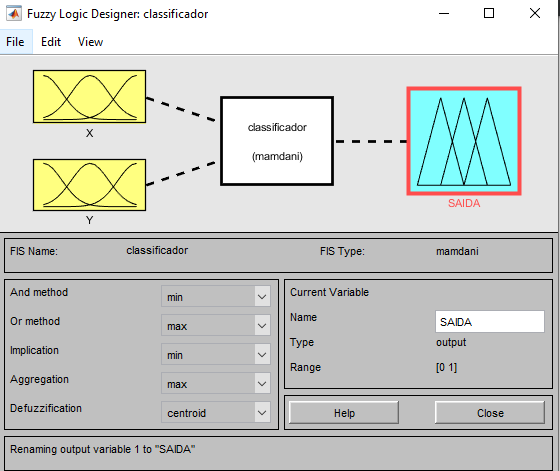

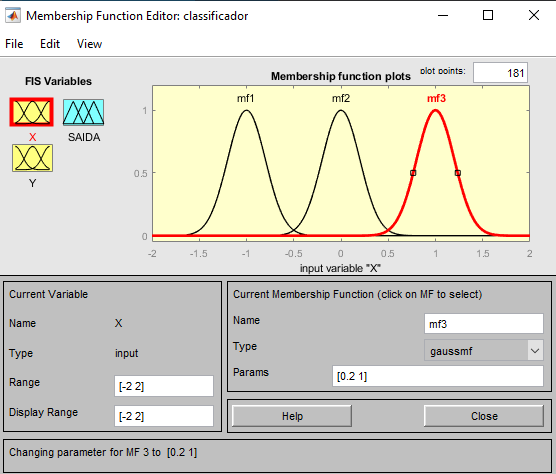

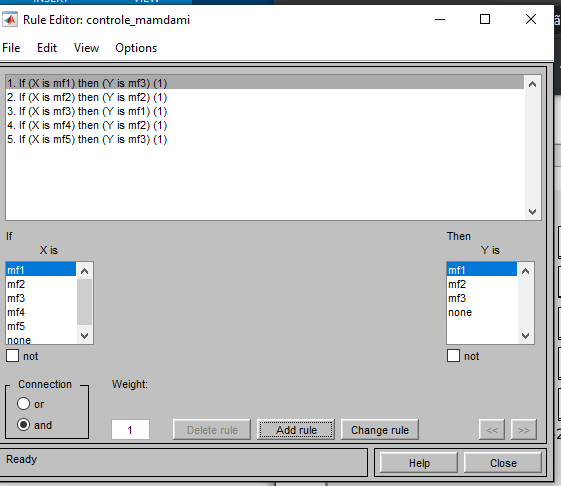

0
